# SPECPARAM



fRange_start = 3;
fRange_end = 123;

df_in = nexObj_fitScp.DF_postOp.df;
f = nexObj_fitScp.DF_postOp.ax.f;
% figure; loglog(df_in)
% frequency range
fCond = (f>=fRange_start)&(f<=fRange_end);
df_in = df_in(fCond);
f = f(fCond);

[specs, scores] = specParam_df(f,df_in);
% plot result
% psd_spec = spec2psd(f,specs{1,1},'fixed','gaussian');
psd_spec = spec2psd(f,specs{1,1},'fixed','doublexp');
figure; plot(f, 10*psd_spec);
hold on
plot(f, df_in);

## SMOOTHING

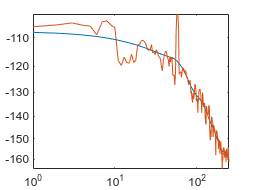

df_in = nexObj_fitScp.DF_postOp.df;
f = nexObj_fitScp.DF_postOp.ax.f;
df_smooth = lowess(df_in', 0.4);
figure; loglog(df_smooth);
hold on; loglog(df_in);

plot(f,diff(df_smooth)./diff(f));

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.

% df_in      = 10*log10(abs(nexObj_fitScp.DF_postOp.df));
df_in      = (nexObj_fitScp.DF_postOp.df);
f          = nexObj_fitScp.DF_postOp.ax.f;
% 60 hz patch
band = (f>56)&(f<62);
band_rep = (f>62)&(f<65);
mean_rep = mean(df_in(band_rep));
df_in(band) = mean_rep;

df_smooth  = lowess(df_in', 0.55);



figure; 
loglog(f, df_smooth, 'LineWidth',1.5); 
hold on; 
loglog(f, df_in, 'LineWidth',1);

% compute derivative on log-log scale
% df_smooth_diff = diff((df_smooth))./diff(f);
% df_smooth_diff = diff(df_smooth) ./ diff(f');
numTicks = 40;
% f_ticks = ((logspace(log(f(1)), log(f(end)), numTicks)));
f_ticks = ((logspace(log10(f(1)), log10(f(end)-1), numTicks)));
f_ticks = (unique(floor(f_ticks)));
df_smooth_resamp = df_smooth(f_ticks);
% df_smooth_diff = diff(df_smooth_resamp) ./ diff(f_ticks');
df_smooth_diff = diff(df_smooth_resamp);
df_smooth_diffDiff = diff(df_smooth_diff);
% f_mid          = (f(1:end-1) + f(2:end)) / 2;   % midpoints for plotting

% figure; plot(f_ticks(1:end-1), df_smooth_diff, 'r', 'LineWidth',1.5);
% figure; semilogx(f_ticks(1:end-1), df_smooth_diff, 'r', 'LineWidth',1.5);
% hold on;
% semilogx(f_ticks(2:end-1),df_smooth_diffDiff)
% 
% figure; loglog(f_ticks(1:end-1), abs(df_smooth_diff), 'r', 'LineWidth',1.5);
% hold on;
% loglog(f_ticks(2:end-1),abs(df_smooth_diffDiff))

figure; semilogx(f_ticks(1:end-1), exp(abs(df_smooth_diff)), 'r', 'LineWidth',1.5);
hold on;
semilogx(f_ticks(2:end-1),exp(abs(df_smooth_diffDiff)))


% legend('Smoothed','Original','Derivative');
% xlabel('Frequency (Hz)');
% ylabel('Power / Derivative');

## ASLS SMOOTHING

% df_in      = 10*log10(abs(nexObj_fitScp.DF_postOp.df));
df_in      = (nexObj_fitScp.DF_postOp.df);
f          = nexObj_fitScp.DF_postOp.ax.f;
% 60 hz patch
band = (f>56)&(f<62);
band_rep = (f>62)&(f<65);
mean_rep = mean(df_in(band_rep));
df_in(band) = mean_rep;

df_smooth  = lowess(df_in', 0.55);



figure; 
loglog(f, df_smooth, 'LineWidth',1.5); 
hold on; 
loglog(f, df_in, 'LineWidth',1);